**Load paths**

start_toolkit

EPANET-MATLAB Toolkit Paths Loaded.


## **How pressure changes during large leakages and fire-fighting?**

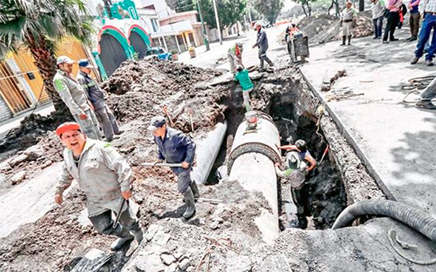          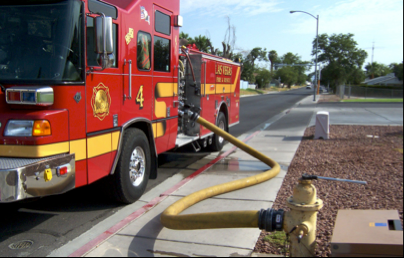

When flow is increased within the network, e.g., due to fire-fighting, the pressure changes near that location. Investigate this change, at node '32'.

G = epanet('Net1.inp');

EPANET version {20200} loaded (EMT version {v2.2.1}).
Loading File "Net1.inp"...
Input File "Net1.inp" loaded successfully.


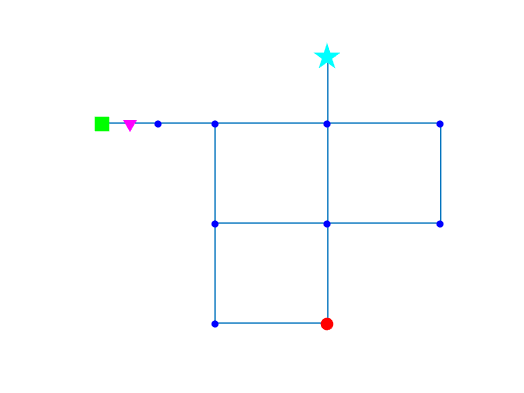

ans =   Axes with properties:

             XLim: [4 76]
             YLim: [2 98]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.13 0.11 0.775 0.815]
            Units: 'normalized'

  Show all properties


nodeID = {'32'};
figure
G.plot('highlightnode', nodeID)

**During fire-fighting, the base demand may increase up to x5. Will there be sufficient pressure?**

idx = G.getNodeIndex(nodeID)

idx =      9


bd = G.getNodeBaseDemands{1}(idx)

bd =    100



demand_multi = 8 % demand multiplicator

demand_multi =      8



d32 = bd *(1:demand_multi) % create the different demands

d32 =    100   200   300   400   500   600   700   800


 
p32min = zeros(1,length(d32)); % initialize variable
for i = 1:length(d32)
    G.setNodeBaseDemands(idx,d32(i));
    p32 = G.getComputedHydraulicTimeSeries.Pressure(:,idx);
    p32min(i) = min(p32);
end

**Plot demand vs pressure**

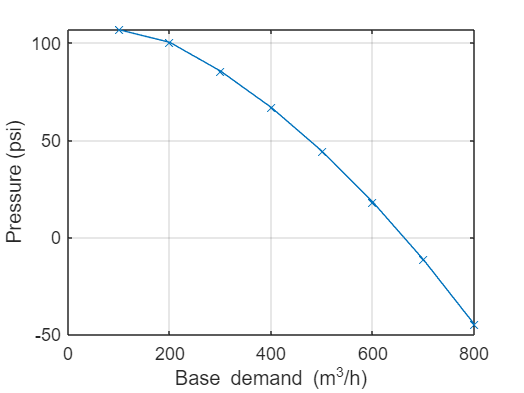

figure 
plot(d32, p32min,'x-')
grid on
xlabel('Base demand (m^3/h)')
ylabel('Pressure (psi)')

How about those negative pressures?

## **Pressure Driven Simulations**

When the pressure is low, it should approximate zero. This is not the default mode of operation in EPANET. However, it's easy to set it up:

type = 'PDA';
pmin = 0;
preq = 0.1;
pexp = 0.5;
G.setDemandModel(type, pmin, preq, pexp)

Let's try this again

demand_multi = 10 % demand multiplicator

demand_multi =     10


d32 = bd *(1:demand_multi) % create the different demands

d32 =          100         200         300         400         500         600         700         800         900        1000


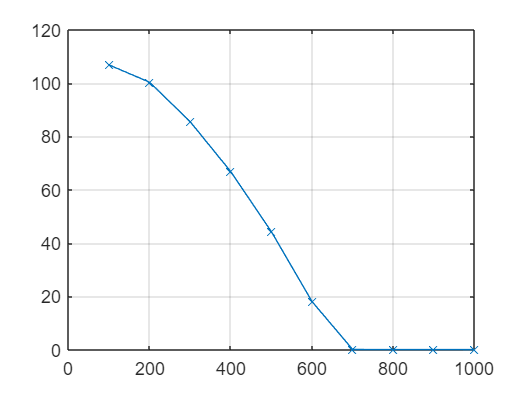


p32min = zeros(1,length(d32)); % initialize variable
for i = 1:length(d32)
    G.setNodeBaseDemands(idx,d32(i));
    p32 = G.getComputedHydraulicTimeSeries.Pressure(:,idx);
    p32min(i) = min(p32);
end

figure 
plot(d32, p32min,'x-')
grid on

G.unload

EPANET Class is unloaded


## **Leakage Simulations**

Simulate leakage in L-Town

Load L-Town benchmark network

d=epanet('L-Town.inp');

EPANET version {20200} loaded (EMT version {v2.2.1}).
Loading File "L-Town.inp"...
Input File "L-Town.inp" loaded successfully.


d.setTimeSimulationDuration(3600)

Simulate L-Town without leak

sim_leak_free = d.getComputedHydraulicTimeSeries;

Simulate leakage:

leak_node = randi([min(double(d.getNodeIndex)), max(double(d.getNodeIndex))],1,1) % random node

leak_node = 100

leak_emit = 2+18*rand; % random leak emiter coefficient [2 20]
emit=d.getNodeEmitterCoeff;
emit=zeros(size(emit));
emit(leak_node)=leak_emit; % set emitter coefficient (leakage) value
d.setNodeEmitterCoeff(emit);
sim_leak = d.getComputedHydraulicTimeSeries;

%%% Plot leakage location:
d.plot

ans =   Axes with properties:

             XLim: [-135.0210 3.1055e+03]
             YLim: [-77.0330 1.7717e+03]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


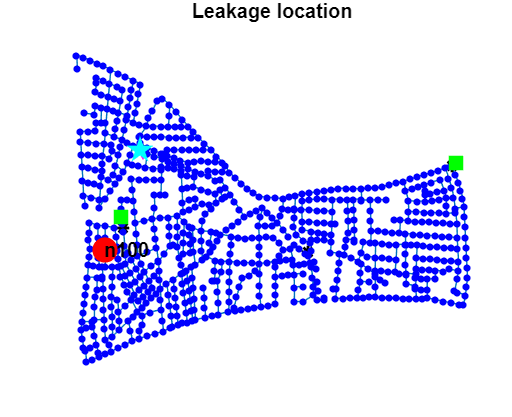

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [360.0000 198.0000 475.0026 387.3000]
       Units: 'pixels'

  Show all properties


legend('off')
coor=d.getNodeCoordinates;
x=coor{1}(leak_node);y=coor{2}(leak_node);
plot(x,y,'o','LineWidth',2,'MarkerEdgeColor','r','MarkerFaceColor','r','MarkerSize',12)
fontweight='bold';
fontsize=11;
for i=1:length(leak_node)
    text(x(i)-5,y(i),d.getNodeNameID{leak_node(i)},'Color','black','FontWeight',fontweight,'Fontsize',fontsize)
end
title('Leakage location')
tightfig()

Get inflows:

res_ind = d.getNodeReservoirIndex; 
for i=1:length(d.getNodeReservoirIndex)
    res_link(i)=find(d.NodesConnectingLinksIndex(:,1)==d.getNodeReservoirIndex(i));
end
Inflows = sim_leak.Flow(:,res_link)

sim_leak = struct with fields:
             Time: [13×1 double]
         Pressure: [13×785 double]
           Demand: [13×785 double]
    DemandDeficit: [13×785 double]
             Head: [13×785 double]
       TankVolume: [13×785 double]
             Flow: [13×909 double]
         Velocity: [13×909 double]
         HeadLoss: [13×909 double]
           Status: [13×909 double]
          Setting: [13×909 double]
           Energy: [13×909 double]
       Efficiency: [13×909 double]
            State: [13×1 double]
        StatusStr: {13×909 cell}
         StateStr: {13×1 cell}


Inflow = sum(Inflows,2);

## **Leakage Detection**

Let's create a dataset with a leakage

Dsim = 100 % Simulation days
K = (1:288*Dsim)'; % time steps of simulation

% compute the fourier values
A6 = [ones(length(K),1) cos((1:FourierTerms)'*w*(K'))' sin((1:FourierTerms)'*w*(K'))']
% create weekly periodicity 
s = A6*rcoef
% create noise
eta = random(pdlog,length(K),1);
y = s.*(1+eta)

figure
plot(y)
grid on
xlim([6624 8306])
ylim([6.6 65.9])

**Simulate a leakage event**

leakSize = 5 % m3/h
leakDay = 60.5
T0 = leakDay * 288;
T1 = T0 + 288*7;
phi = zeros(length(K),1);
phi(T0:T1) = leakSize;
y2 = y + phi

figure
plot(y2)
grid on
xlim([15502 20656])
ylim([6.3 66.7])

**Minimum Night Flow Analysis**

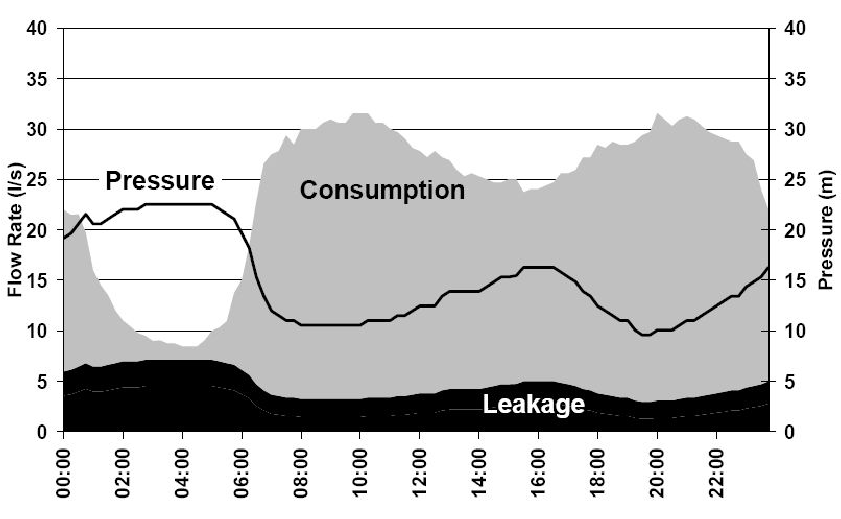

- Basic idea is that each night the uncertainty is low

- Demand is low

- Pressure is high

- Easier to detect leakages

% compute the minimum flow for each day
Y = reshape(y2,288,100)
MF = min(Y)
grid on
plot(MF)
grid on
line([100,0],[9,9])

**Detecting changes**

- Change detection algorithms

- Limit checking, change in mean

- Cumulative Sum (CUSUM)


% Find change points
[changeIndices,segmentMean] = ischange(MF,'Threshold',3);

% Visualize results
clf
plot(MF,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on

% Plot segments between change points
plot(segmentMean,'Color',[64 64 64]/255,'DisplayName','Segment mean')

% Plot change points
x = repelem(find(changeIndices),3);
y3 = repmat([ylim(gca) NaN]',nnz(changeIndices),1);
plot(x,y3,'Color',[51 160 44]/255,'LineWidth',1,'DisplayName','Change points')
title(['Number of change points: ' num2str(nnz(changeIndices))])

hold off
legend
clear segmentMean x y3


Limit checking, the most simple detection algorithm

threshold = 9
alert = MF > threshold

figure
plot(alert, 'r-')

A different approach would be to take a window of minimum (night) flows, and compare them with the new minimum flow. If it exceeds a precalculated distance, the issue an alert.